clc;
clear;
close all;


function psd_val = psd_at_2hz(signal_data, fs)
% PSD_AT_2HZ Calculate power spectral density at 2 Hz
%   PSD_AT_2HZ(signal_data, fs) calculates and displays the power spectral 
%   density of signal_data, highlighting the component at 2 Hz
%
%   signal_data: Input time series signal
%   fs: Sampling frequency in Hz

% Input validation
if nargin < 2
    error('Both signal_data and sampling frequency (fs) are required');
end

% Signal length
N = length(signal_data);

% Time vector
t = (0:N-1)/fs;

% Calculate frequency resolution
df = fs/N;

% Calculate frequency vector
freq = 0:df:fs/2;

% Calculate PSD using Welch's method
window = hamming(min(256, length(signal_data)));
noverlap = floor(length(window)/2);
[pxx, f] = pwelch(signal_data, window, noverlap, [], fs);

% Find index closest to 2 Hz
[~, idx_2hz] = min(abs(f - 2));

% Display results
% fprintf('PSD analysis results:\n');
% fprintf('Sampling frequency: %.2f Hz\n', fs);
% fprintf('Frequency resolution: %.4f Hz\n', df);
% fprintf('PSD at 2 Hz (or closest frequency %.4f Hz): %.6e\n', f(idx_2hz), pxx(idx_2hz));
psd_val= pxx(idx_2hz);
% 
% % Plot the signal in time domain
% figure;
% subplot(2,1,1);
% plot(t, signal_data);
% title('Time Domain Signal');
% xlabel('Time (s)');
% ylabel('Amplitude');
% grid on;
% 
% % Plot the PSD
% subplot(2,1,2);
% plot(f, 10*log10(pxx));
% hold on;
% plot(f(idx_2hz), 10*log10(pxx(idx_2hz)), 'ro', 'MarkerSize', 8);
% text(f(idx_2hz)*1.1, 10*log10(pxx(idx_2hz)), ['  ' num2str(f(idx_2hz), '%.2f') ' Hz']);
% title('Power Spectral Density');
% xlabel('Frequency (Hz)');
% ylabel('PSD (dB/Hz)');
% grid on;
% hold off;
% 
% % Zoom in around 2 Hz for better visibility
% xlim([max(0, 2-2) 2+2]);

end

ind_avg_fs = 266196

ind_std_fs = 1.6911e+05

ind_avg_fs = 258818

ind_std_fs = 1.6486e+05

ind_avg_fs = 266052

ind_std_fs = 1.6962e+05

ind_avg_fs = 262146

ind_std_fs = 1.6767e+05

ind_avg_fs = 266210

ind_std_fs = 1.6997e+05

ind_avg_fs = 264559

ind_std_fs = 1.7109e+05

ind_avg_fs = 263826

ind_std_fs = 1.6773e+05

ind_avg_fs = 264519

ind_std_fs = 1.6922e+05

ind_avg_fs = 267387

ind_std_fs = 1.7046e+05

ind_avg_fs = 259865

ind_std_fs = 1.6576e+05

ind_avg_fs = 262990

ind_std_fs = 1.6680e+05

ind_avg_fs = 261372

ind_std_fs = 1.6548e+05

ind_avg_fs = 258856

ind_std_fs = 1.6464e+05

ind_avg_fs = 261564

ind_std_fs = 1.6609e+05

ind_avg_fs = 264122

ind_std_fs = 1.6807e+05

ind_avg_fs = 260046

ind_std_fs = 1.6397e+05

ind_avg_fs = 272783

ind_std_fs = 1.7404e+05

ind_avg_fs = 272147

ind_std_fs = 1.7485e+05

ind_avg_fs = 267922

ind_std_fs = 1.7224e+05

ind_avg_fs = 275477

ind_std_fs = 1.7851e+05

ind_avg_fs = 271024

ind_std_fs = 1.7316e+05

ind_avg_fs = 269684

ind_std_fs = 1.6862e+05

ind_avg_fs = 267034

ind_std_fs = 1.6877e+05

ind_avg_fs = 267643

ind_std_fs = 1.6973e+05

ind_avg_fs = 276077

ind_std_fs = 1.7731e+05

ind_avg_fs = 271800

ind_std_fs = 1.7390e+05

ind_avg_fs = 278535

ind_std_fs = 1.7926e+05

ind_avg_fs = 275048

ind_std_fs = 1.7534e+05

ind_avg_fs = 274478

ind_std_fs = 1.7459e+05

ind_avg_fs = 270115

ind_std_fs = 1.7415e+05

ind_avg_fs = 271251

ind_std_fs = 1.7312e+05

ind_avg_fs = 276376

ind_std_fs = 1.7764e+05

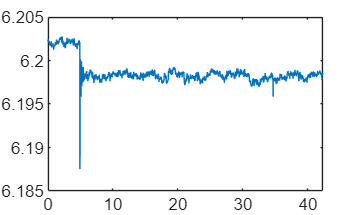

cd = '1-sensor_thickness';

addpath(cd);

%% make sure to use double quotation!!!
speaker = "lg"; %% "sm" or "lg"

thickness = 0.5:0.5:2;
% thickness = 2;

datalog = [];

peak_value = [];
bpm_diffs = [];

if speaker == "sm"
    voltage = 2:0.5:3.5;

    voltage = [1.7, voltage];
elseif speaker == "lg"
    voltage = 2:0.5:5.5;
end

rms_values = zeros(length(voltage)*length(thickness), 6);
counter = 0;

for j = 1:length(thickness)

    for i = 1:length(voltage)
        counter = counter + 1;

        ind_name = strcat('ind_',num2str(thickness(j)),'mm_',num2str(voltage(i)),'V_',speaker,'.csv');
        % ind_name = strcat('sync_ind_',num2str(voltage(i)),'V.csv');

        %% read ind data

        raw_ind_data = readtable(ind_name);

        deltaTimes = raw_ind_data{:,'evmSampleDeltaMs'};  % extract the delta time column

        %% not do batch average
        diffTime =  raw_ind_data{:,'logDeltaMs'};
        

        % %% do batch average
        % % Set a threshold to detect a "big" delta that signals a new batch.
        % % In your data, the big delta values (that mark a batch) are >> 1 (ms).
        % threshold = 1;
        % 
        % % Identify the starting indices for each batch.
        % batchStartIdx = find(deltaTimes >= threshold);
        % N = length(deltaTimes);
        % 
        % % We'll create an array to hold the computed absolute timestamps.
        % absTime = zeros(N,1);
        % 
        % % --- Process Batches 2 to End ---
        % % We skip the first batch for now (because its big delta is not reliable).
        % % For batches 2 onward, we use the same idea as before:
        % % For a batch that starts at a big delta value, evenly distribute that delta
        % % across the points in the batch and add the cumulative time.
        % %
        % % For batch 2, we define the starting time T0 arbitrarily (e.g. 0).
        % % For subsequent batches, T0 is updated to be the last timestamp from the previous batch.
        % if length(batchStartIdx) < 2
        %     error('Not enough batches to compute average sample interval.');
        % end
        % 
        % T0 = 0;  % initialize cumulative time
        % for b = 2:length(batchStartIdx)
        %     startIdx = batchStartIdx(b);
        %     if b < length(batchStartIdx)
        %         endIdx = batchStartIdx(b+1) - 1;
        %     else
        %         endIdx = N;
        %     end
        % 
        %     nPoints = endIdx - startIdx + 1;
        %     bigDelta = deltaTimes(startIdx);
        % 
        %     % Evenly distribute the big delta across the nPoints.
        %     if nPoints > 1
        %         dt_batch = linspace(0, bigDelta, nPoints);
        %     else
        %         dt_batch = bigDelta;
        %     end
        % 
        %     absTime(startIdx:endIdx) = T0 + dt_batch;
        %     T0 = absTime(endIdx);  % update cumulative time for next batch
        % end
        % 
        % % --- Compute Average Sampling Interval from Batches 2+ ---
        % allDt = [];
        % for b = 2:length(batchStartIdx)
        %     startIdx = batchStartIdx(b);
        %     if b < length(batchStartIdx)
        %         endIdx = batchStartIdx(b+1) - 1;
        %     else
        %         endIdx = N;
        %     end
        % 
        %     if (endIdx - startIdx) >= 1
        %         allDt = [allDt; diff(absTime(startIdx:endIdx))];
        %     end
        % end
        % 
        % avgDt = mean(allDt);
        % 
        % % --- Process Batch 1 using Back-Extrapolation ---
        % % Batch 1 is from batchStartIdx(1) to (batchStartIdx(2)-1).
        % firstBatchStart = batchStartIdx(1);
        % firstBatchEnd   = batchStartIdx(2) - 1;
        % n_first = firstBatchEnd - firstBatchStart + 1;
        % 
        % % Assume that the first sample of batch 2 is correctly computed as a reference.
        % T_batch2_start = absTime(batchStartIdx(2));
        % 
        % % We want the last sample of batch 1 to be exactly one avgDt before T_batch2_start.
        % % Then, we assign batch 1 timestamps evenly spaced backwards.
        % % For example, if there are N₁ samples, assign:
        % %    T_batch1 = linspace( T_batch2_start - n_first*avgDt, T_batch2_start - avgDt, n_first)
        % absTime(firstBatchStart:firstBatchEnd) = linspace(T_batch2_start - n_first*avgDt, T_batch2_start - avgDt, n_first)';
        % 
        % absTime = absTime - absTime(1);
        % 
        % raw_ind_data.absTime = absTime;
        % 
        % diffTime = raw_ind_data{batchStartIdx,'logDeltaMs'};
        % 

        % 
        % ind_data = raw_ind_data{batchStartIdx,'DATA0_uH'};  %% data used for inductive sensor

        ind_time = 0;
        for k = 1:length(diffTime)
            time2add = ind_time(end) + diffTime(k);
            ind_time = [ind_time, time2add];
        end



        ind_time = ind_time(2:end);
        ind_time = ind_time - ind_time(1);

        % try with all data
        % ind_time = raw_ind_data.absTime;
        ind_data = raw_ind_data{:,'DATA0_uH'};


        ind_time = ind_time ./ 1000;        %% time scale used for inductive sensor, in seconds




        ind_diff_time = ind_time(2:end) - ind_time(1:end-1);
        duplicate_index = find(ind_diff_time == 0);

        ind_time(duplicate_index+1) = [];       %% time scale used for accelerometer, in seconds
        ind_data(duplicate_index+1) = [];       %% data used for accelerometer




        ind_diff_time = ind_time(2:end) - ind_time(1:end-1);

        ind_fs = 1 ./ ind_diff_time;
        ind_avg_fs = round(mean(ind_fs))
        ind_std_fs = std(ind_fs)


        figure(1)
        plot(ind_time,ind_data);

acc_avg_fs = 115

acc_std_fs = 88.5955

acc_avg_fs = 113

acc_std_fs = 82.3792

acc_avg_fs = 115

acc_std_fs = 88.3754

acc_avg_fs = 117

acc_std_fs = 99.0270

acc_avg_fs = 116

acc_std_fs = 90.7912

acc_avg_fs = 116

acc_std_fs = 95.9207

acc_avg_fs = 114

acc_std_fs = 85.6180

acc_avg_fs = 115

acc_std_fs = 89.9114

acc_avg_fs = 115

acc_std_fs = 90.6435

acc_avg_fs = 114

acc_std_fs = 84.7040

acc_avg_fs = 115

acc_std_fs = 89.3702

acc_avg_fs = 113

acc_std_fs = 79.0821

acc_avg_fs = 115

acc_std_fs = 89.8229

acc_avg_fs = 114

acc_std_fs = 89.7946

acc_avg_fs = 113

acc_std_fs = 79.1198

acc_avg_fs = 113

acc_std_fs = 82.1448

acc_avg_fs = 115

acc_std_fs = 88.2308

acc_avg_fs = 114

acc_std_fs = 86.7339

acc_avg_fs = 114

acc_std_fs = 85.6259

acc_avg_fs = 117

acc_std_fs = 98.8044

acc_avg_fs = 116

acc_std_fs = 93.7641

acc_avg_fs = 115

acc_std_fs = 92.2805

acc_avg_fs = 116

acc_std_fs = 90.8839

acc_avg_fs = 113

acc_std_fs = 85.0628

acc_avg_fs = 113

acc_std_fs = 81.5497

acc_avg_fs = 112

acc_std_fs = 72.7645

acc_avg_fs = 114

acc_std_fs = 86.6768

acc_avg_fs = 115

acc_std_fs = 93.2613

acc_avg_fs = 113

acc_std_fs = 81.9855

acc_avg_fs = 115

acc_std_fs = 90.1277

acc_avg_fs = 113

acc_std_fs = 79.5763

acc_avg_fs = 113

acc_std_fs = 82.7806

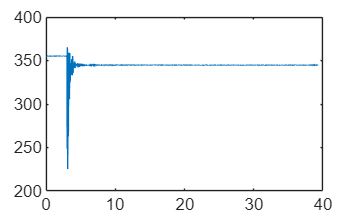

        % acc_name = strcat('sync_acc_',num2str(voltage(i)),'V.csv');
        %
        % acc_raw = readtable(acc_name);
        %
        % acc_data = acc_raw{:,7};
        % timems = acc_raw{:,1};
        % acc_time = timems ./ 1000;

        acc_name = strcat('acc_',num2str(thickness(j)),'mm_',num2str(voltage(i)),'V_',speaker,'.txt');
        %% read acc data
        % Open the file for reading
        fid = fopen(acc_name, 'r');
        if fid == -1
            error('File cannot be opened.');
        end

        % Initialize arrays for valid data
        timeSecs = [];
        value1  = [];
        value2  = [];

        % Define a regular expression pattern.
        % This pattern looks for:
        %  - One or more digits for hours, minutes, seconds, and milliseconds.
        %  - The literal " -> " between the time and the two numeric values.
        %  - Two floating-point numbers separated by a comma.
        pattern = '^(\d+):(\d+):(\d+):(\d+)\s*->\s*(-?\d+\.\d+),(-?\d+\.\d+)$';

        while ~feof(fid)
            tline = fgetl(fid);

            % Use regexp to see if the line matches the complete pattern.
            tokens = regexp(tline, pattern, 'tokens');

            if ~isempty(tokens)
                % Convert token strings to numbers.
                nums = cellfun(@str2double, tokens{1});
                h  = nums(1);
                m  = nums(2);
                s  = nums(3);
                ms = nums(4);
                v1 = nums(5);
                v2 = nums(6);

                % Convert the time into seconds.
                timeInSec = h*3600 + m*60 + s + ms/1000;

                % Append to our arrays
                timeSecs(end+1, 1) = timeInSec;
                value1(end+1, 1)  = v1;
                value2(end+1, 1)  = v2;
            end
            % If tokens is empty, the line is incomplete or doesn’t match the format.
            % In that case, it is automatically disregarded.
        end

        % Close the file
        fclose(fid);

        % Display the results (as a table for clarity)
        acc_data =  value2;

        acc_time = timeSecs - timeSecs(1);

        acc_diff_time = acc_time(2:end) - acc_time(1:end-1);

        duplicate_index = find(acc_diff_time == 0);

        acc_time(duplicate_index+1) = [];       %% time scale used for accelerometer, in seconds

        acc_data(duplicate_index+1) = [];       %% data used for accelerometer

        acc_diff_time = acc_time(2:end) - acc_time(1:end-1);

        acc_fs = 1 ./ acc_diff_time;
        acc_avg_fs = round(mean(acc_fs))
        acc_std_fs = std(acc_fs)


        figure(2)
        plot(acc_time,acc_data)


        smpa_idx_start = round(length(acc_time)*0.4);
        smpa_idx_stop = round(length(acc_time)*0.7);

        smpi_idx_start = round(length(ind_time)*0.4);
        smpi_idx_stop = round(length(ind_time)*0.7);

        smp_acc_data = acc_data(smpa_idx_start:smpa_idx_stop, :);
        smp_acc_time = acc_time(smpa_idx_start:smpa_idx_stop, :);

        smp_ind_data = ind_data(smpi_idx_start:smpi_idx_stop, :);
        smp_ind_time = ind_time(:, smpi_idx_start:smpi_idx_stop);



        f_low = 1.5;            % Lower cutoff frequency in Hz
        f_high = 2.5;           % Upper cutoff frequency in Hz
        order = 3;              % Filter order (higher = sharper cutoff)

        Wn = [f_low, f_high] / (400);  % Normalize frequencies to Nyquist
        [b, a] = butter(order, Wn, 'bandpass');

        filt_smp_ind_data = filtfilt(b, a, smp_ind_data);

        Wn = [f_low, f_high] / (acc_avg_fs/2);  % Normalize frequencies to Nyquist
        [b, a] = butter(order, Wn, 'bandpass');
        filt_smp_acc_data = filtfilt(b, a, smp_acc_data);

        % filt_smp_ind_data = (filt_smp_ind_data - mean(filt_smp_ind_data))/std(filt_smp_ind_data);
        % filt_smp_acc_data = (filt_smp_acc_data - mean(filt_smp_acc_data))/std(filt_smp_acc_data);

        [smp_acc_pks, smpa_locs] = findpeaks(filt_smp_acc_data, "MinPeakDistance", 9);
        [smp_ind_pks, smpi_locs] = findpeaks(filt_smp_ind_data, "MinPeakDistance", 20);

        % figure()
        % plot(filt_smp_acc_data)
        % hold on;
        % plot(smpa_locs, smp_acc_pks, 'ro', 'MarkerSize', 10);
        % hold off;
        % 
        % figure()
        % plot(smp_ind_data)
        % 
        % figure()
        % plot(filt_smp_ind_data)
        % hold on;
        % plot(smpi_locs, smp_ind_pks, 'ro', 'MarkerSize', 10);
        % hold off;
        
        smp_acc_feat = mean(smp_acc_pks);
        smp_ind_feat = mean(smp_ind_pks);

        % smp_acc_feat = rms(smp_acc_data);
        % smp_ind_feat = rms(smp_ind_data);
        
        
        rms_values(counter, 1) = smp_acc_feat;
        rms_values(counter, 2) = smp_ind_feat;
        rms_values(counter, 3) = length(smp_acc_pks);
        rms_values(counter, 4) = length(smp_ind_pks);
        rms_values(counter, 5) = smp_acc_time(end) - smp_acc_time(1);
        rms_values(counter, 6) = smp_ind_time(end) - smp_ind_time(1);



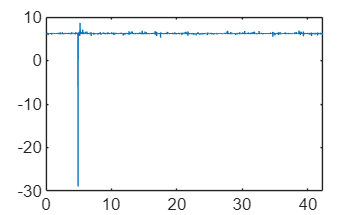

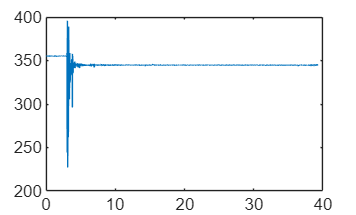

        
        %% resample data
        fs = 100;
        rs_acc_time = acc_time(1):1/fs:acc_time(end);
        rs_ind_time = ind_time(1):1/fs:ind_time(end);

        rs_acc = interp1(acc_time,acc_data,rs_acc_time,'spline');
        rs_ind = interp1(ind_time,ind_data,rs_ind_time,'spline');

        figure(22)
        plot(rs_ind_time,rs_ind)

        figure(33)
        plot(rs_acc_time,rs_acc)

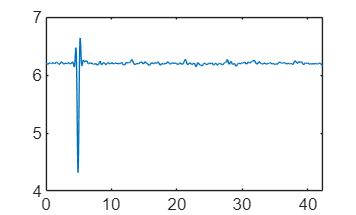

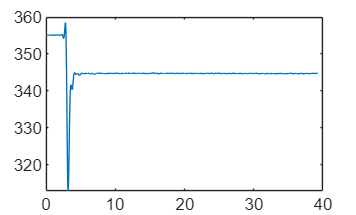

        %% data alignment
        [~,ind_max_raw] = max(rs_ind(1:1000));
        [~,acc_max_raw] = max(rs_acc(1:1000));

        [~,ind_min_raw] = min(rs_ind(1:1000));
        [~,acc_min_raw] = min(rs_acc(1:1000));

        if ind_max_raw > ind_min_raw
            ind_max_raw = ind_min_raw;
        end

        if acc_max_raw > acc_min_raw
            acc_max_raw = acc_min_raw;
        end

        raw_max_ind_time = rs_ind_time(ind_max_raw);
        raw_max_acc_time = rs_acc_time(acc_max_raw);

        ind_timestamp = round(raw_max_ind_time*100);
        acc_timestamp = round(raw_max_acc_time*100);


        %% data filtering

        %% Low pass filter
        % fs = 100;           % Sample rate in Hz (adjust as needed)
        cutoff_freq = 2.1;    % Cutoff frequency in Hz
        filter_order = 4;    % Filter order (adjust as needed)

        % lpf = designfilt('lowpassiir', ...
        %     'FilterOrder', filter_order, ...
        %     'HalfPowerFrequency', cutoff_freq, ...
        %     'SampleRate', fs, ...
        %     'DesignMethod', 'butter');

        [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');

        lp_acc= filtfilt(b, a, rs_acc);
        lp_ind= filtfilt(b, a, rs_ind);

        figure(3)
        plot(rs_ind_time,lp_ind);

        figure(4)
        plot(rs_acc_time,lp_acc);

        %% Moving average
        mv_acc = smooth(lp_acc, 10);
        mv_ind = smooth(lp_ind, 10);


        % %% High pass filter
        % % fs = 100;           % Sample rate in Hz (adjust as needed)
        % cutoff_freq = 1.9;    % Cutoff frequency in Hz
        % filter_order = 4;    % Filter order (adjust as needed)
        % 
        % % lpf = designfilt('lowpassiir', ...
        % %     'FilterOrder', filter_order, ...
        % %     'HalfPowerFrequency', cutoff_freq, ...
        % %     'SampleRate', fs, ...
        % %     'DesignMethod', 'butter');
        % 
        % [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
        % 
        % hp_acc= filtfilt(b, a, mv_acc);
        % hp_ind= filtfilt(b, a, mv_ind);
        % 
        % 
        % figure(2346346);
        % plot(rs_ind_time, hp_ind)
        % xlim([0 50])
        % 
        % figure(346);
        % plot(rs_acc_time, hp_acc)
        % % ylim([-0.05 0.05])
        % xlim([0 50])

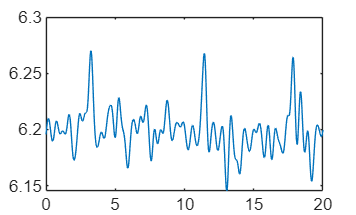

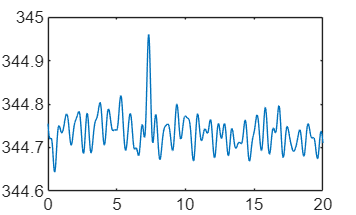

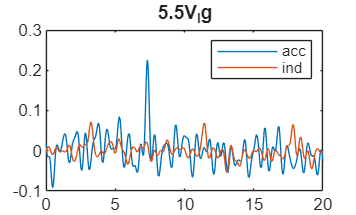

        %% data clipping

        time_after_tap = 5;
        time_after_start = 20;


        ind_stt_idx = round(ind_timestamp+fs*time_after_tap);
        ind_stp_idx = round(ind_stt_idx + fs*time_after_start);

        acc_stt_idx = round(acc_timestamp+fs*time_after_tap);
        acc_stp_idx = round(acc_stt_idx + fs*time_after_start);

        clip_acc_data = mv_acc(acc_stt_idx:acc_stp_idx);
        clip_ind_data = mv_ind(ind_stt_idx:ind_stp_idx);

        clip_acc_time = rs_acc_time(acc_stt_idx:acc_stp_idx);
        clip_ind_time = rs_ind_time(ind_stt_idx:ind_stp_idx);

        clip_time = clip_acc_time - clip_acc_time(1);

        figure(5)
        plot(clip_time,clip_ind_data);

        figure(6)
        plot(clip_time,clip_acc_data);

        mean_center_acc = clip_acc_data - mean(clip_acc_data);
        mean_center_ind = clip_ind_data - mean(clip_ind_data);

        figure(66)
        % comparison between raw data (inductance vs acc)
        plot(clip_time,mean_center_acc,clip_time, mean_center_ind);
        title(strcat(num2str(voltage(i)),'V_',speaker))
        legend('acc','ind')

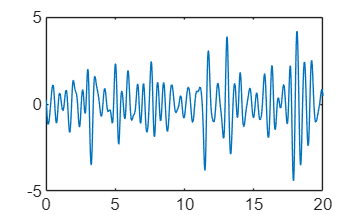

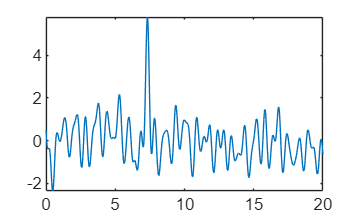

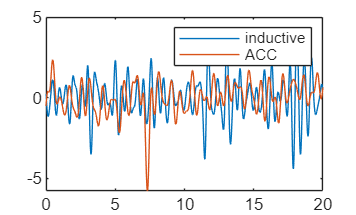

        %% double differentiation
        norm_acc = (clip_acc_data - mean(clip_acc_data))/std(clip_acc_data);
        norm_ind = (clip_ind_data - mean(clip_ind_data))/std(clip_ind_data);

        ind_diff = diff(clip_ind_data) ./ (1/fs);
        ind_diff_diff = diff(ind_diff) ./ (1/fs);

        figure(7)
        plot(clip_time(3:end),ind_diff_diff);

        figure(8)
        plot(clip_time, norm_acc);

        figure(88)
        plot(clip_time(2:end-1),ind_diff_diff,clip_time, -norm_acc);
        legend("inductive",'ACC')

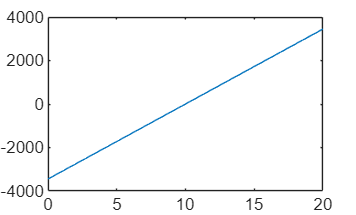

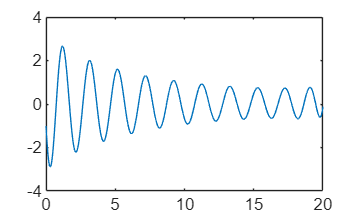

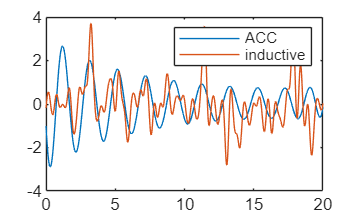

        %% double integration
        norm_acc = (clip_acc_data - mean(clip_acc_data))/std(clip_acc_data);
        norm_ind = (clip_ind_data - mean(clip_ind_data))/std(clip_ind_data);

        acc_integral = cumtrapz(clip_time, clip_acc_data);
        shift_acc_integral = acc_integral - mean(acc_integral);


        acc_inte_integral = cumtrapz(clip_time,shift_acc_integral);

        hp_acc_int_int = highpass(acc_inte_integral,0.5,fs);

        norm_acc_int_int = (hp_acc_int_int - mean(hp_acc_int_int))/std(hp_acc_int_int);

        figure(27)
        plot(clip_time,shift_acc_integral);

        figure(28)
        plot(clip_time, norm_acc_int_int);

        figure(188)
        plot(clip_time,norm_acc_int_int,clip_time, norm_ind);
        legend("ACC","inductive")

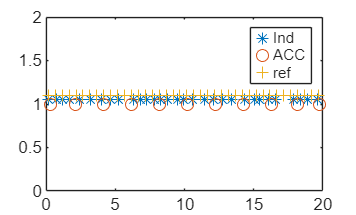

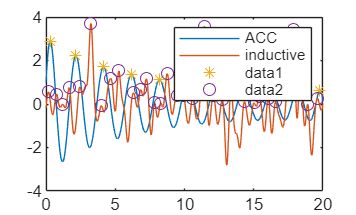

        peak_width = 10;
        [acc_peaks, acc_peak_loc] = findpeaks(-norm_acc_int_int,'MinPeakWidth',peak_width);
        [ind_peaks, ind_peak_loc] = findpeaks(norm_ind,'MinPeakWidth',peak_width);

        ref_time = clip_time(ind_peak_loc):0.5:20;

        figure(5624)
        plot(clip_time(ind_peak_loc),1.05*ones(length(ind_peak_loc),1),'*');
        hold on
        plot(clip_time(acc_peak_loc),ones(length(acc_peak_loc),1),'o');
        plot(ref_time,1.1*ones(length(ref_time),1),'+');
        hold off
        legend('Ind','ACC','ref')
        ylim([0 2])

        figure(1818)
        plot(clip_time,-norm_acc_int_int,clip_time, norm_ind);
        legend("ACC","inductive")
        hold on
        plot(clip_time(acc_peak_loc),acc_peaks,'*');
        plot(clip_time(ind_peak_loc),ind_peaks,'o');
        hold off

        acc_peak_time = clip_time(acc_peak_loc);
        ind_peak_time = clip_time(ind_peak_loc);

        diff_acc_peak_time = acc_peak_time(2:end) - acc_peak_time(1:end-1);
        diff_ind_peak_time = ind_peak_time(2:end) - ind_peak_time(1:end-1);

        diff_acc_peak_freq = 1./diff_acc_peak_time;
        diff_ind_peak_freq = 1./diff_ind_peak_time;
        
        bpm_diff = length(ind_peaks) - 40;
        bpm_diffs = [bpm_diffs; bpm_diff];

        diff_acc_peak_mean = mean(diff_acc_peak_freq);
        diff_acc_peak_std = std(diff_acc_peak_freq);

        diff_ind_peak_mean = mean(diff_ind_peak_freq);
        diff_ind_peak_std = std(diff_ind_peak_freq);

        peak2log = [diff_acc_peak_mean, diff_acc_peak_std,diff_ind_peak_mean, diff_ind_peak_std];
        peak_value = [peak_value;peak2log];



Maximum correlation:0.33804 at lag383


Maximum correlation:-0.1776 at lag1535


Maximum correlation:0.21075 at lag1528


Maximum correlation:0.22289 at lag279


Maximum correlation:0.26675 at lag1162


Maximum correlation:0.25824 at lag1642


Maximum correlation:0.37785 at lag1133


Maximum correlation:0.20083 at lag175


Maximum correlation:-0.25947 at lag1459


Maximum correlation:-0.16522 at lag1222


Maximum correlation:0.23987 at lag1142


Maximum correlation:-0.17104 at lag-192


Maximum correlation:0.32531 at lag1161


Maximum correlation:0.26991 at lag250


Maximum correlation:0.3459 at lag1210


Maximum correlation:-0.34626 at lag827


Maximum correlation:-0.34043 at lag927


Maximum correlation:-0.17436 at lag99


Maximum correlation:-0.20908 at lag1245


Maximum correlation:-0.23004 at lag1317


Maximum correlation:-0.26296 at lag785


Maximum correlation:0.30209 at lag125


Maximum correlation:0.25758 at lag1615


Maximum correlation:0.25795 at lag1471


Maximum correlation:-0.23518 at lag1286


Maximum correlation:0.19914 at lag441


Maximum correlation:0.20705 at lag559


Maximum correlation:-0.32588 at lag1886


Maximum correlation:0.24894 at lag473


Maximum correlation:0.18078 at lag1048


Maximum correlation:0.19249 at lag764


Maximum correlation:-0.31789 at lag186


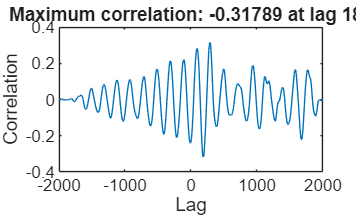

 % Calculate cross-correlation
        [correlation, lags] = xcorr(norm_ind, -norm_acc_int_int, 'coeff');

        % Find maximum correlation and its position
        [max_corr, max_idx] = max(correlation);
        lag_at_max = lags(max_idx);

        [min_corr, min_idx] = min(correlation);
        lag_at_min = lags(min_idx);

        if abs(min_corr) > abs(max_corr)
            overall_corr = min_corr;
            lag = lag_at_min;
            norm_acc = -norm_acc;
        else
            overall_corr = max_corr;
            lag = lag_at_max;
        end

        % overall_corr = max_corr;
        % lag = lag_at_max;

        disp(strcat('Maximum correlation: ', num2str(overall_corr), ' at lag ', num2str(lag)));

        % Plot results
        figure(9);
        plot(lags, correlation);
        xlabel('Lag');
        ylabel('Correlation');
        title(['Maximum correlation: ', num2str(overall_corr), ' at lag ', num2str(lag)]);

Maximum coherence: 0.472 at frequency 0.29452 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.30899 at frequency 0.073631 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.21707 at frequency 0.11045 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.46668 at frequency 0.44179 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.55916 at frequency 0.23317 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.27289 at frequency 0.23317 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.21341 at frequency 0.12272 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.55788 at frequency 0.12272 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.32379 at frequency 0.036816 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.42483 at frequency 0.34361 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.38258 at frequency 0.085903 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.30767 at frequency 0.23317 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.27304 at frequency 0.14726 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.66352 at frequency 0.061359 Hz


    "Coherence quality: "    "Strong coherence"



Maximum coherence: 0.22689 at frequency 0.14726 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.22882 at frequency 0.25771 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.3151 at frequency 0.29452 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.43092 at frequency 0.024544 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.48644 at frequency 0.3068 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.46854 at frequency 0.12272 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.61069 at frequency 0.061359 Hz


    "Coherence quality: "    "Strong coherence"



Maximum coherence: 0.4698 at frequency 0.024544 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.40732 at frequency 0.036816 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.56989 at frequency 2.3562 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.50608 at frequency 0.14726 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.4826 at frequency 0.3927 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.27591 at frequency 0.35588 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.31985 at frequency 0.061359 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.50229 at frequency 3.1416 Hz


    "Coherence quality: "    "Moderate coherence"



Maximum coherence: 0.27173 at frequency 0.57678 Hz


    "Coherence quality: "    "Weak coherence"



Maximum coherence: 0.63325 at frequency 0.42951 Hz


    "Coherence quality: "    "Strong coherence"



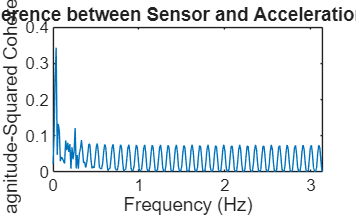

Maximum coherence: 0.34308 at frequency 0.036816 Hz


    "Coherence quality: "    "Weak coherence"



        % Calculate coherence
        [cxy, f] = mscohere(norm_ind, norm_acc_int_int);

        % Plot coherence
        figure(10);
        plot(f, cxy);
        xlabel('Frequency (Hz)');
        ylabel('Magnitude-Squared Coherence');
        title('Coherence between Sensor and Acceleration Data');

        % Find maximum coherence and corresponding frequency
        [max_coh, max_idx] = max(cxy);
        freq_at_max = f(max_idx);

        % Interpret the coherence strength
        if max_coh >= 0.8
            coh_quality = "Very strong coherence";
        elseif max_coh >= 0.6
            coh_quality = "Strong coherence";
        elseif max_coh >= 0.4
            coh_quality = "Moderate coherence";
        elseif max_coh >= 0.2
            coh_quality = "Weak coherence";
        else
            coh_quality = "Very weak coherence";
        end

        disp(['Maximum coherence: ', num2str(max_coh), ' at frequency ', num2str(freq_at_max), ' Hz']);
        disp(['Coherence quality: ', coh_quality]);

        data2log = [thickness(j),voltage(i),overall_corr,max_coh];
        datalog = [datalog;data2log];
    end
end

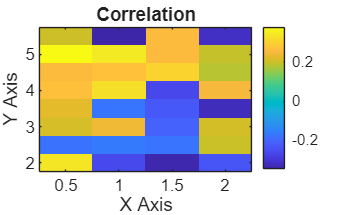


function plotGrid(data,titleWord)

% Suppose 'data' is an N-by-3 matrix: [x, y, intensity]
x = data(:,1);
y = data(:,2);
intensity = data(:,3);

% Get unique grid values
xi = unique(x);
yi = unique(y);

% Check that the grid size matches the data length
if numel(xi)*numel(yi) ~= numel(x)
    error('Data does not appear to be on a regular grid.');
end

% Reshape intensity into a matrix. Here we assume that the data is
% ordered so that intensity varies fastest along x and then y.
I = reshape(intensity, numel(yi), numel(xi));

% Plot the heatmap. 'imagesc' will display the matrix as an image.
figure;
imagesc(xi', yi', I);
set(gca, 'YDir','normal'); % Ensures y-axis is in the correct orientation
colorbar;
xlabel('X Axis');
ylabel('Y Axis');
title(titleWord);
end

figure(11)
plotGrid(datalog(:,1:3),'Correlation')

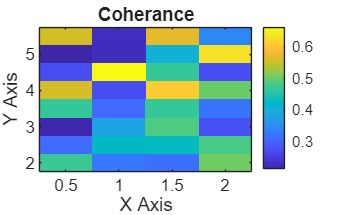


figure(12)
plotGrid(datalog(:,[1:2,4]),'Coherance')

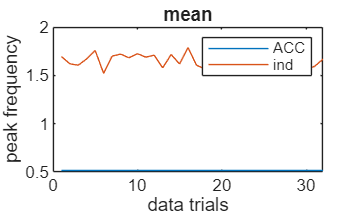

figure(23561)
plot(peak_value(:,1));
hold on
plot(peak_value(:,3));
hold off
legend('ACC','ind')
title('mean')
xlabel('data trials')
ylabel('peak frequency')

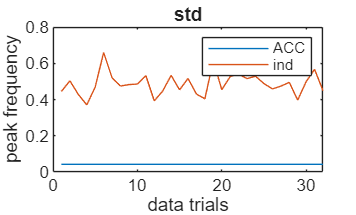

figure(231234)
plot(peak_value(:,2));
hold on
plot(peak_value(:,4));
hold off
legend('ACC','ind')
title('std')
xlabel('data trials')
ylabel('peak frequency')

% Create a figure
figure('Position', [100, 100, 800, 1000]);

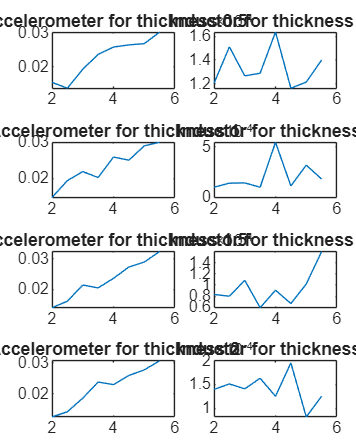



% Create a 4×2 tiled layout
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(thickness)
    nexttile;
    plot(voltage, rms_values((i-1)*length(voltage)+1:(i-1)*length(voltage)+length(voltage), 1))
    title("Accelerometer for thickness " + thickness(i))
    nexttile;
    plot(voltage, rms_values((i-1)*length(voltage)+1:(i-1)*length(voltage)+length(voltage), 2))
    title("Inductor for thickness " + thickness(i))
end

bpm_diff_comp = (rms_values(:, 3)./(rms_values(:,5)./60)) - (rms_values(:, 4)./(rms_values(:,6)./60))

bpm_diff_comp =    61.3006
   64.1618
   55.1862
   54.7318
   61.5024
   62.5226
   57.4063
   65.6978
   60.9222
   58.8936
